# NUM on the MITgcm, UVic and ECCO transport matrices

Three simulated years of `setupNUMmodel` on each of three transport matrix configurations, started from the same initial conditions, compared.

The commit and date this was last run for are printed below, so the stored output can be traced back to the state of the code that produced it.

% This notebook lives in Notebooks/, but inputRead and loadNUMmodelLibrary
% resolve ../input/input.yaml against the working directory, so move into
% matlab/ before anything else is called.
nbDir = fileparts(mfilename('fullpath'));
if isempty(nbDir), nbDir = pwd; end
root = fileparts(nbDir);
addpath(fullfile(root, 'matlab'));
cd(fullfile(root, 'matlab'));

[okC, commit] = system(sprintf('git -C "%s" rev-parse --short HEAD', root));
[okB, branch] = system(sprintf('git -C "%s" rev-parse --abbrev-ref HEAD', root));
[~,   dirty]  = system(sprintf('git -C "%s" status --porcelain --untracked-files=no', root));
if okC == 0 && okB == 0
    if isempty(strtrim(dirty)), state = ''; else, state = ', working tree modified'; end
    fprintf('Run for commit %s on branch %s%s\n', strtrim(commit), strtrim(branch), state);
else
    fprintf('Run from %s (git commit unavailable)\n', root);
end

Run for commit e8bf199 on branch UVicTM, working tree modified


fprintf('Run on %s\n', string(datetime('now','Format','yyyy-MM-dd HH:mm')));

Run on 2026-09-30 21:05


## What is being compared

**What "the same initial conditions" means here.** The three grids are different shapes, so an identical state vector is not possible. All runs take `simulateGlobal`'s default: nitrogen and silicate from each grid's own `N0`/|Si0| field, and DOC and every biomass class uniform from `p.u0`. So the biology starts identical everywhere, and the nutrients start from the same physical field mapped onto each grid.

**What differs besides the grid.** Each configuration is run with the transport step its matrices are built for, and the Euler step that goes with it - see the comments in `parametersGlobal`. The table below prints both, because a difference between the panels is grid **and** timestep, not grid alone. ECCO additionally takes its light from the `parday.mat` it ships on its own grid, where the other two compute it.

All paired figures below share one colour scale and one set of axis limits, so the panels can be read against each other directly.

## Load, or run

Each run is three simulated years. MITgcm and UVic take minutes; ECCO is the 1 degree grid, 682604 wet boxes against MITgcm_2.8deg's 52749, and takes closer to an hour and several GB of output. All three are cached as `.mat` files in `Notebooks/cache`, so every figure below can be regenerated without running the model again. That directory is git-ignored: the caches run to several gigabytes and are output, not source. Delete it to force a re-run.

nYears = 3;

dirCache = fullfile(nbDir, 'cache');
if ~isfolder(dirCache), mkdir(dirCache); end

% iTM is the configuration index parametersGlobal takes
cfg = struct( ...
    'file', {'sim_mitgcm.mat', 'sim_uvic.mat', 'sim_ecco.mat'}, ...
    'iTM',  {1,                3,              2});

nRuns = numel(cfg);
runs  = cell(1, nRuns);
for i = 1:nRuns
    fileCache = fullfile(dirCache, cfg(i).file);
    if isfile(fileCache)
        load(fileCache, 'sim');
    else
        p = setupNUMmodel(bParallel=true);
        p = parametersGlobal(p, cfg(i).iTM);
        p.tEnd = nYears*365; p.tSave = 365/12;
        sim = simulateGlobal(p);
        save(fileCache, 'sim', '-v7.3');
    end
    runs{i} = sim;
    clear sim
end

names    = cell(1, nRuns);   % as stored, for legends with Interpreter none
texNames = cell(1, nRuns);   % escaped, for titles that go through TeX
iFinal   = cell(1, nRuns);   % the saves making up the final year
for i = 1:nRuns
    names{i}    = runs{i}.p.TMname;
    % panelGlobal puts its title through the TeX interpreter, where a bare
    % underscore subscripts the next character
    texNames{i} = strrep(names{i}, '_', '\_');
    iFinal{i}   = finalYear(runs{i});
end

% The maps, the sections and the spectrum below average over the *final*
% simulated year rather than the whole run. Averaging all three would mix the
% settled state with the spin-up away from the uniform initial biomass, which
% is visible in the time series in the next two sections.
fprintf('averaging window: days %.0f-%.0f of %d\n', ...
    min(runs{1}.t(iFinal{1})), max(runs{1}.t(iFinal{1})), nYears*365);

averaging window: days 730-1095 of 1095


## The three configurations

Sizes, timesteps and whether nitrogen was conserved over the three years.

nLon = zeros(nRuns,1); nLat = nLon; nDepth = nLon;
dtT  = zeros(nRuns,1); dtE  = dtT;  relN   = dtT; nWet = nLon;
for i = 1:nRuns
    s = runs{i};
    nLon(i)   = numel(s.x);
    nLat(i)   = numel(s.y);
    nDepth(i) = numel(s.z);
    nWet(i)   = sum(~isnan(reshape(s.N(1,:,:,:), 1, [])));
    dtT(i)    = s.p.dtTransport;
    dtE(i)    = s.p.dt;
    [~, relN(i)] = checkConservation(s, false);
end

tbl = table(names(:), nLon, nLat, nDepth, nWet, dtT, dtE, relN, ...
    'VariableNames', {'matrices','nLon','nLat','nDepth','nWet', ...
                      'dtTransport','dt','relNbalance'});
disp(tbl)

          matrices           nLon    nLat    nDepth      nWet       dtTransport       dt       relNbalance
    _____________________    ____    ____    ______    _________    ___________    ________    ___________

    {'MITgcm_2.8deg'    }    128      64       15          52749          0.5           0.1    3.7824e-07 
    {'UVicOSUpicdefault'}    100     100       19          87307      0.33333      0.083333    6.6321e-13 
    {'MITgcm_ECCO'      }    360     160       23      6.826e+05          0.5           0.1    1.8273e-07 



## Total nitrogen through the run

`calcGlobalN` sums over cells and returns grammes, so this is one of the few quantities that can be compared between the grids without qualification. A flat line is the conservation check; the level is set by the nutrient field each grid was initialised with.

**This is the caveat that matters for everything below.** "The same initial conditions" is weaker than it sounds: the grids are initialised from the same physical nutrient field, but mapping it onto different grids does not preserve the total, and the runs do not start on equal stock. The absolute starting values are printed below; a biomass difference of that order should not be read as an effect of the circulation. The curves are plotted relative to each run's own start for that reason.

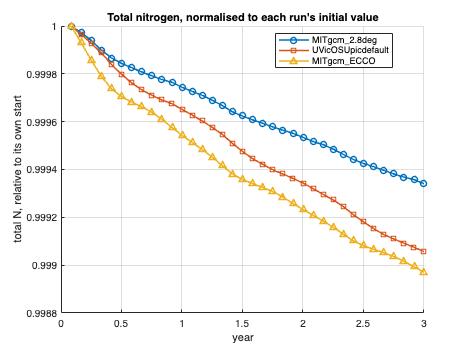

figure
hold on
markers = {'-o','-s','-^'};
N0 = zeros(nRuns,1);
for i = 1:nRuns
    Ni = calcGlobalN(runs{i});
    N0(i) = Ni(1);
    plot(runs{i}.t/365, Ni/Ni(1), markers{i}, 'LineWidth', 1.5)
end
hold off
xlabel('year'); ylabel('total N, relative to its own start')
legend(names, 'Interpreter','none', 'Location','best')
title('Total nitrogen, normalised to each run''s initial value')
grid on


for i = 1:nRuns
    fprintf('initial total N: %-20s %.3e g  (%.3f x %s)\n', ...
        names{i}, N0(i), N0(i)/N0(1), names{1});
end

initial total N: MITgcm_2.8deg        5.011e+11 g  (1.000 x MITgcm_2.8deg)
initial total N: UVicOSUpicdefault    5.788e+11 g  (1.155 x MITgcm_2.8deg)
initial total N: MITgcm_ECCO          5.676e+11 g  (1.133 x MITgcm_2.8deg)


## Global mean biomass through the run

Depth-integrated with `calcIntegrateGlobal` to g/m^2, then averaged over the globe with cos(latitude) weights so the grids can be put on one axis. Three years is long enough to show the initial transient away from the uniform starting biomass separately from the seasonal cycle that follows it, which is the reason for running more than one.

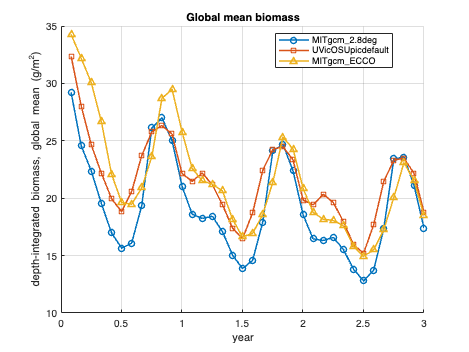

bSeries = cell(1, nRuns);
figure
hold on
for i = 1:nRuns
    bSeries{i} = globalMeanSeries(runs{i}, runs{i}.B);
    plot(runs{i}.t/365, bSeries{i}, markers{i}, 'LineWidth', 1.5)
end
hold off
xlabel('year'); ylabel('depth-integrated biomass, global mean (g/m^2)')
legend(names, 'Interpreter','none', 'Location','best')
title('Global mean biomass')
grid on


for i = 1:nRuns
    b = bSeries{i};
    fprintf('%-20s first-year mean %.3f g/m^2, final-year mean %.3f g/m^2\n', ...
        names{i}, mean(b(runs{i}.t <= 365)), mean(b(iFinal{i})));
end

MITgcm_2.8deg        first-year mean 21.987 g/m^2, final-year mean 17.429 g/m^2
UVicOSUpicdefault    first-year mean 24.359 g/m^2, final-year mean 19.634 g/m^2
MITgcm_ECCO          first-year mean 26.096 g/m^2, final-year mean 18.466 g/m^2


## Community Sheldon spectrum

`calcCommunitySpectrum` builds the community spectrum across all groups as defined in Andersen and Visser (2023), Box V. It is given the globally averaged biomass concentration of each size class, so the grids are reduced the same way before the spectrum is formed. All runs use the same `setupNUMmodel`, so the underlying size grid is identical.

`calcCommunitySpectrum` indexes the biomass matrix by row using `sim.t`, and averages over the second half of the run when no time index is given. Here it is given the final-year indices explicitly, so the spectrum covers the same window as the maps below rather than a window of the function's choosing.

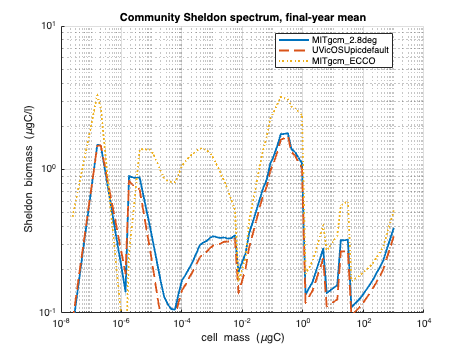

styles = {'-','--',':'};
figure
hold on
for i = 1:nRuns
    [mc, BSheldon] = calcCommunitySpectrum(meanConcByClass(runs{i}), runs{i}, ...
                                           find(iFinal{i}));
    loglog(mc, BSheldon, styles{i}, 'LineWidth', 1.8)
end
hold off
set(gca, 'XScale','log', 'YScale','log')
xlabel('cell mass (\mugC)'); ylabel('Sheldon biomass (\mugC/l)')
legend(names, 'Interpreter','none', 'Location','best')
title('Community Sheldon spectrum, final-year mean')
ylim([0.1 10])
grid on

## Depth-integrated biomass

Mean over the final simulated year, on a shared colour scale. The grids are different resolutions, so the panels are shown separately rather than differenced.

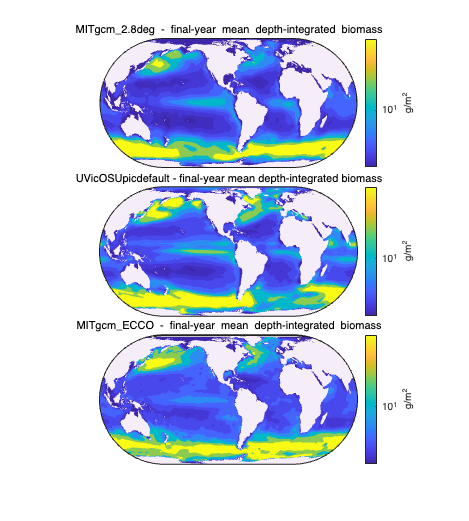

maps = cell(1, nRuns);
for i = 1:nRuns
    maps{i} = mapField(runs{i}, iFinal{i});
end
levels = sharedLevels(maps);

figure('Position',[100 100 900 1000])
tiledlayout(nRuns,1, 'TileSpacing','compact')
for i = 1:nRuns
    nexttile
    panelGlobal(runs{i}.x, runs{i}.y, maps{i}, levels, sProjection='eckert4', ...
        sTitle=sprintf('%s - final-year mean depth-integrated biomass', texNames{i}), ...
        sUnits='g/m^2');
    set(gca, 'colorscale', 'log')
end

## Zonal mean sections

Biomass averaged over longitude and over the final year, latitude against depth, on a shared colour scale and a shared depth axis, so a grid's extra layers read as depth range rather than as a change of scale.

The depth axis is logarithmic. Almost all of the structure sits in the top couple of hundred metres, which a linear axis to 5000 m compresses into a sliver; a log axis gives the euphotic zone the room the signal is actually in. It also puts the three grids' differing layer thicknesses on a footing where the shallow layers, where they differ most, are visible.

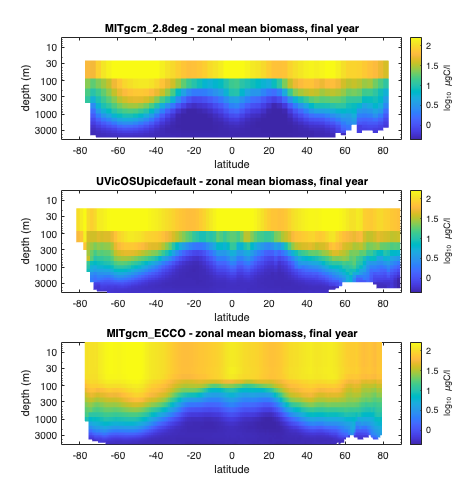

zonals = cell(1, nRuns);
depthLims = [inf 0];
for i = 1:nRuns
    zonals{i} = zonalField(runs{i}, iFinal{i});
    zPos = runs{i}.z(runs{i}.z > 0);          % a log axis cannot show z = 0
    depthLims = [min(depthLims(1), min(zPos)), max(depthLims(2), max(zPos))];
end
clim2 = sharedLimits(zonals);

figure('Position',[100 100 900 960])
tiledlayout(nRuns,1, 'TileSpacing','compact')
for i = 1:nRuns
    nexttile
    drawZonal(runs{i}, zonals{i}, clim2, depthLims)
    title(sprintf('%s - zonal mean biomass, final year', names{i}), 'Interpreter','none')
end

## Helper functions

function idx = finalYear(sim)
    % Logical index of the saves lying in the last 365 days of the run. The
    % tolerance keeps the save that falls exactly on the boundary out, so the
    % window holds one year of saves and not one more.
    idx = sim.t(:)' > max(sim.t) - 365 + 1e-6;
end

function w = latWeights(sim)
    % cos(latitude), so a global mean is not dominated by the poles
    w = cos(deg2rad(sim.y(:)));
end

function m = weightedNanMean(a, w)
    % a is [x, y], w is the latitude weight for each y. Land is NaN or zero.
    a(a == 0) = NaN;
    W = repmat(w(:)', size(a,1), 1);
    valid = ~isnan(a);
    m = sum(a(valid).*W(valid)) / sum(W(valid));
end

function s = globalMeanSeries(sim, field)
    % Depth-integrate to g/m^2, then area-weighted global mean, per save
    Bint = calcIntegrateGlobal(sim, field);        % [time, x, y]
    w = latWeights(sim);
    s = zeros(size(Bint,1),1);
    for i = 1:size(Bint,1)
        s(i) = weightedNanMean(squeeze(Bint(i,:,:)), w);
    end
end

function B = meanConcByClass(sim)
    % Globally averaged concentration of each size class, as [time, class].
    % cos(latitude) weighted over the wet cells, so the grids reduce the same
    % way. Units are those of the model state, which is what
    % calcCommunitySpectrum expects.
    %
    % Every save gets a row, including the spin-up ones. That is deliberate:
    % calcCommunitySpectrum selects rows with indices derived from sim.t, so
    % size(B,1) must equal numel(sim.t). Restrict the window with its iTime
    % argument, never by handing it a pre-trimmed matrix.
    [nt, nx, ny, nz, nc] = size(sim.B);
    w = latWeights(sim);
    W = repmat(reshape(w, [1 ny 1]), [nx 1 nz]);   % [x, y, z]
    B = zeros(nt, nc);
    for k = 1:nc
        for i = 1:nt
            a = double(squeeze(sim.B(i,:,:,:,k)));  % [x, y, z]
            valid = ~isnan(a) & a ~= 0;
            B(i,k) = sum(a(valid).*W(valid)) / sum(W(valid));
        end
    end
end

function lims = sharedLimits(fields)
    % One colour scale across every panel, robust to a few extreme cells
    v = [];
    for i = 1:numel(fields)
        vi = fields{i}(:);
        v = [v; vi(isfinite(vi))]; %#ok<AGROW>
    end
    lims = [prctile(v, 1) prctile(v, 99)];
    if ~(lims(2) > lims(1)), lims = [min(v) max(v)]; end
end

function a = mapField(sim, idx)
    % Mean depth-integrated biomass over the saves selected by idx, [x, y],
    % left linear because panelGlobal takes the field itself and log-spaced
    % contour levels. idx defaults to every save.
    if nargin < 2 || isempty(idx), idx = true(1, numel(sim.t)); end
    Bint = calcIntegrateGlobal(sim, sim.B);      % [time, x, y]
    a = squeeze(mean(Bint(idx,:,:), 1));
    a(a <= 0) = NaN;
end

function levels = sharedLevels(fields)
    % One set of log-spaced contour levels across every map, so the panels are
    % drawn on the same colour scale
    v = [];
    for i = 1:numel(fields)
        vi = fields{i}(:);
        v = [v; vi(isfinite(vi) & vi > 0)]; %#ok<AGROW>
    end
    lo = prctile(v, 1); hi = prctile(v, 99);
    if ~(hi > lo), lo = min(v); hi = max(v); end
    levels = 10.^linspace(log10(lo), log10(hi), 10);
end

function Z = zonalField(sim, idx)
    if nargin < 2 || isempty(idx), idx = true(1, numel(sim.t)); end
    B = squeeze(sum(sim.B, 5));             % sum the spectrum -> [time, x, y, z]
    B = squeeze(mean(B(idx,:,:,:), 1));     % mean over idx    -> [x, y, z]
    B(B == 0) = NaN;
    Z = squeeze(mean(B, 1, 'omitnan'));     % zonal mean       -> [y, z]
    Z = log10(Z);
end

function drawZonal(sim, Z, lims, depthLims)
    % Depth is plotted as a positive quantity on a reversed log axis, rather
    % than as negative metres, because a log scale needs strictly positive
    % values. The axis still reads surface at the top, deep at the bottom.
    pcolor(sim.y, sim.z, Z'); shading flat
    set(gca, 'YScale', 'log', 'YDir', 'reverse')
    clim(lims)
    c = colorbar; c.Label.String = 'log_{10} \mugC/l';
    xlabel('latitude'); ylabel('depth (m)')
    xlim([-90 90]); ylim(depthLims)
    % The default log ticks put a single label across the three decades this
    % axis spans. Set decade and half-decade ticks explicitly, and label them
    % as plain metres rather than powers of ten.
    ticks = [1 3 10 30 100 300 1000 3000 10000];
    ticks = ticks(ticks >= depthLims(1) & ticks <= depthLims(2));
    yticks(ticks); ytickformat('%g')
end